## Clément interpolation discussion

### Preliminars

Mesh on which the *given* (or input) function will be projected and filtered. Consider the following discretization of a [0,1]x[0,1] domain:

x1 = linspace(0,1,50);
x2 = linspace(0,1,50);

[xv,yv] = meshgrid(x1,x2);

[F,V] = mesh2tri(xv,yv,zeros(size(xv)),'x');

m.coord  = V(:,1:2);
m.connec = F;
mesh = Mesh(m);

Moreover, we need a *given L2 *function:

s.fHandle = @(x) 1-heaviside((x(1,:,:)-0.5).^2+(x(2,:,:)-0.5).^2-0.3.^2);
s.ndimf   = 1;
s.mesh    = mesh;
fun       = AnalyticalFunction(s);

### Projections

Let's project previous L2 function into a P0 FE function:

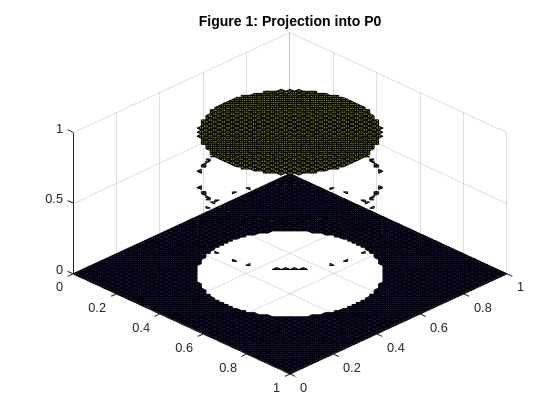

fP0 = fun.project('P0');
fP0.plot()
view(45,45)
title('Figure 1: Projection into P0')

Let's now project it into a P1 FE function:

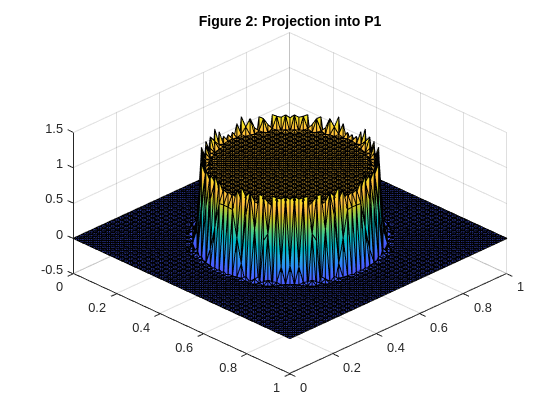

fP1 = fun.project('P1');
fP1.plot()
view(45,45)
title('Figure 2: Projection into P1')

Let's now project it into a P1 FE function using a lumped mass matrix:

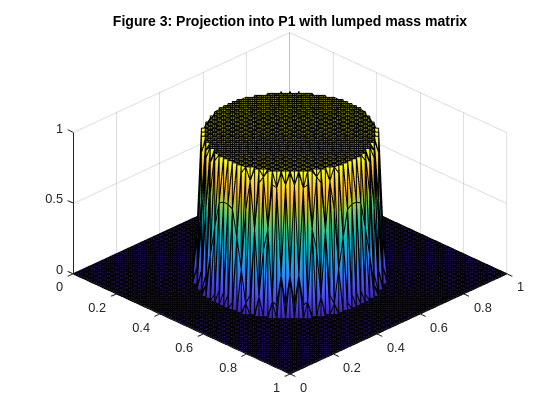

newProj = Projector_toP1Lumped(s);
fP1Lump = newProj.project(fun);
fP1Lump.plot()
view(45,45)
title('Figure 3: Projection into P1 with lumped mass matrix')

### PDE Filter

Let's create now a PDE filter, which smooths isotropically just the internal boundaries:

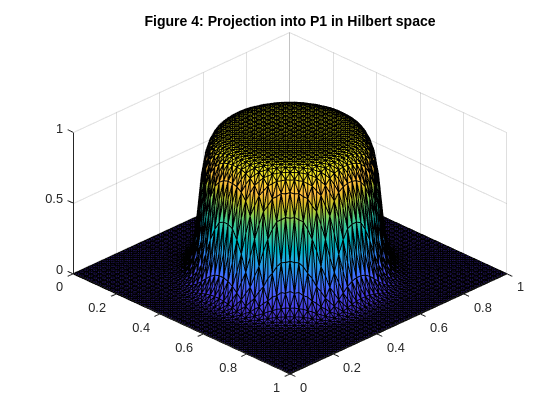

ss.filterType    = 'PDE';
ss.mesh          = mesh;
ss.boundaryType  = 'Neumann';
ss.metric        = 'Isotropy';
filter           = Filter.create(ss);
fP1PDE           = filter.compute(fun,'QUADRATICMASS');
fP1PDE.plot()
view(45,45)
title('Figure 4: Projection into P1 in Hilbert space')

### Kernel Filter

Let's create now a Kernel filter based in Clément interpolators. We have two working approaches.


$$Approach \ A: \ x_r=I_{ki}\cdot lump[(I_{ki}^T\cdot M_{kl}\cdot I_{lj})]^{-1}\cdot(I_{ki}^T\cdot RHS_k) \\
Approach \ B: \ x_r=lump((I_{ki}\cdot M_{ij}))^{-1}\cdot(I_{ki}\cdot RHS_i)$$
 

Let's start with approach A.

Let's filter from P0 to P0:

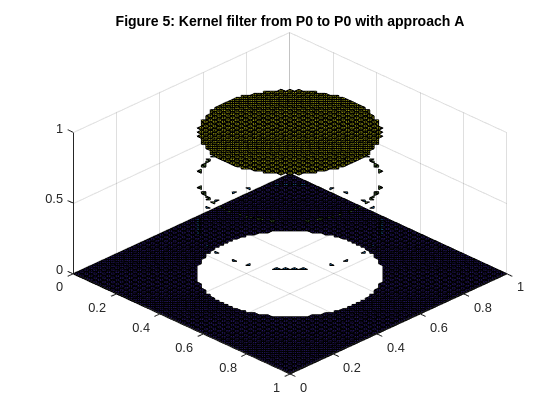

ss.filterType = 'P1';
ss.mesh       = mesh;
ss.approach   = 'A';
ss.test       = P0Function.create(mesh,1);
ss.trial      = P0Function.create(mesh,1);
filter        = Filter.create(ss);
fP0P0         = filter.compute(fun,'QUADRATICMASS');
fP0P0.plot()
view(45,45)
title('Figure 5: Kernel filter from P0 to P0 with approach A')

Let's filter from P0 to P1:

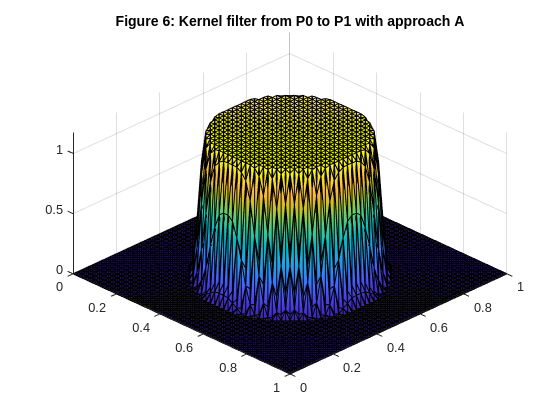

ss.test       = P0Function.create(mesh,1);
ss.trial      = P1Function.create(mesh,1);
filter        = Filter.create(ss);
fP0P1         = filter.compute(fun,'QUADRATICMASS');
fP0P1.plot()
view(45,45)
title('Figure 6: Kernel filter from P0 to P1 with approach A')

Let's filter from P1 to P0:

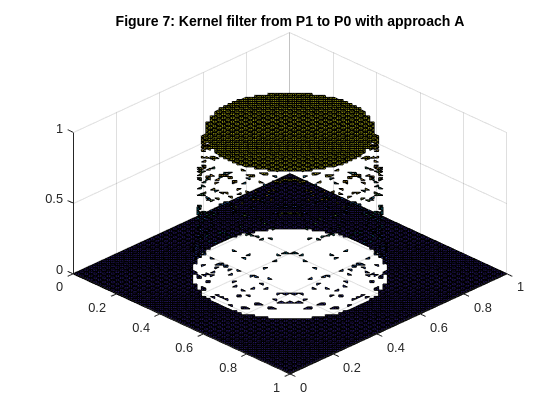

ss.test       = P1Function.create(mesh,1);
ss.trial      = P0Function.create(mesh,1);
filter        = Filter.create(ss);
fP1P0         = filter.compute(fun,'QUADRATICMASS');
fP1P0.plot()
view(45,45)
title('Figure 7: Kernel filter from P1 to P0 with approach A')

Let's filter from P1 to P1:

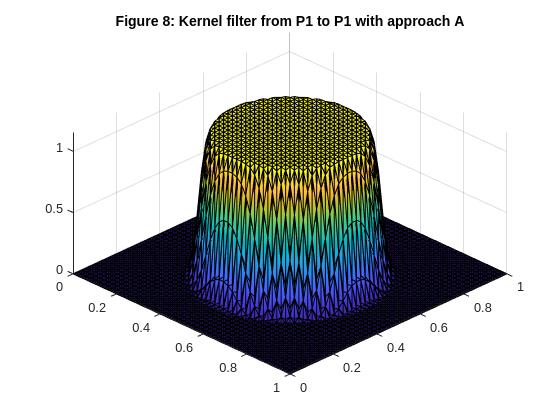

ss.test       = P1Function.create(mesh,1);
ss.trial      = P1Function.create(mesh,1);
filter        = Filter.create(ss);
fP1P1         = filter.compute(fun,'QUADRATICMASS');
fP1P1.plot()
view(45,45)
title('Figure 8: Kernel filter from P1 to P1 with approach A')

Let's finish with approach B.

Let's filter from P0 to P0:

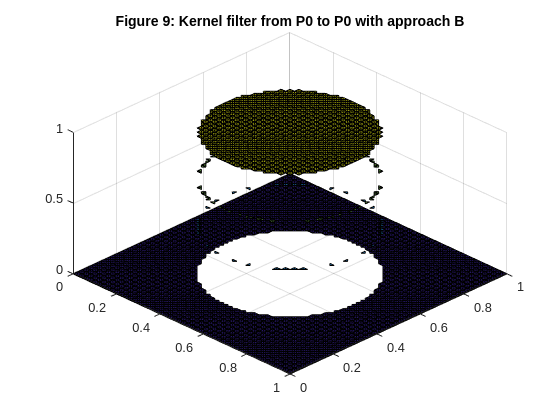

ss.approach   = 'B';
ss.test       = P0Function.create(mesh,1);
ss.trial      = P0Function.create(mesh,1);
filter        = Filter.create(ss);
fP0P0         = filter.compute(fun,'QUADRATICMASS');
fP0P0.plot()
view(45,45)
title('Figure 9: Kernel filter from P0 to P0 with approach B')

Let's filter from P0 to P1:

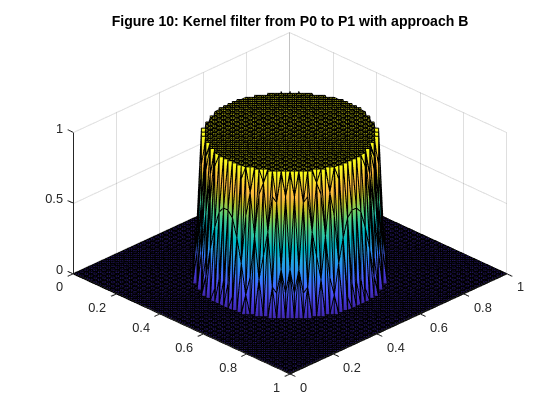

ss.test       = P0Function.create(mesh,1);
ss.trial      = P1Function.create(mesh,1);
filter        = Filter.create(ss);
fP0P1         = filter.compute(fun,'QUADRATICMASS');
fP0P1.plot()
view(45,45)
title('Figure 10: Kernel filter from P0 to P1 with approach B')

Let's filter from P1 to P0:

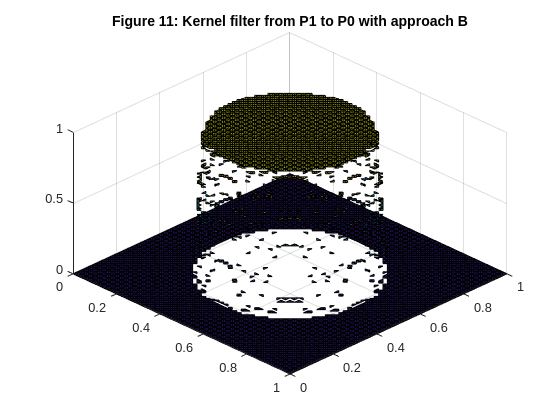

ss.test       = P1Function.create(mesh,1);
ss.trial      = P0Function.create(mesh,1);
filter        = Filter.create(ss);
fP1P0         = filter.compute(fun,'QUADRATICMASS');
fP1P0.plot()
view(45,45)
title('Figure 11: Kernel filter from P1 to P0 with approach B')

Let's filter from P1 to P1:

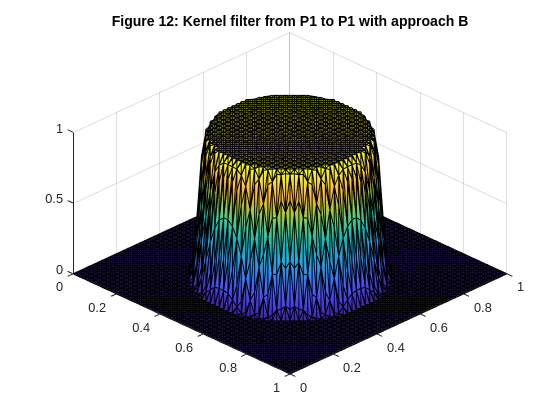

ss.test       = P1Function.create(mesh,1);
ss.trial      = P1Function.create(mesh,1);
filter        = Filter.create(ss);
fP1P1         = filter.compute(fun,'QUADRATICMASS');
fP1P1.plot()
view(45,45)
title('Figure 12: Kernel filter from P1 to P1 with approach B')

Original P0 to P1:

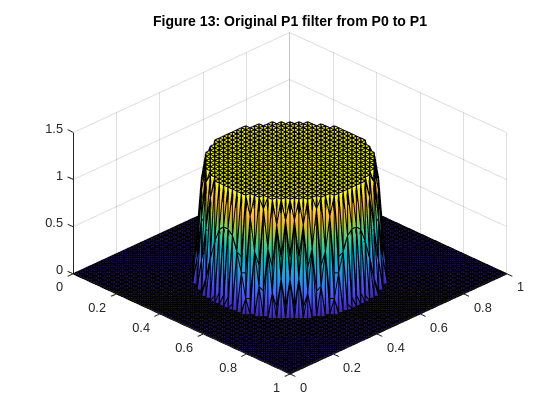

ss.approach   = 'C';
ss.test       = P1Function.create(mesh,1);
ss.trial      = P0Function.create(mesh,1);
filter        = Filter.create(ss);
fP0P0         = filter.compute(fun,'QUADRATICMASS');
fP0P0.plot()
view(45,45)
title('Figure 13: Original P1 filter from P0 to P1')